# Matlab Data Analysis Tutorial: Analysis of Galaxy Clusters from the Sloane Digital Sky Survey

## Introduction

Matlab provides an excellent suite of tools for rapidly constructing applications which you can use to prepare and process data. In this live script we explore use the following matlab tools to explore a data set gathered from the Sloane digital sky survey.   

- [Scatter plots](https://uk.mathworks.com/help/matlab/ref/scatter.html?searchHighlight=scatter%20plot&s_tid=doc_srchtitle)

- [Histogram bin counts](https://uk.mathworks.com/help/matlab/ref/histcounts.html?searchHighlight=histcounts&s_tid=doc_srchtitle)

- [Interactive controls for live scripts](https://uk.mathworks.com/help/matlab/matlab_prog/add-interactive-controls-to-a-live-script.html?searchHighlight=live%20script%20control&s_tid=doc_srchtitle)

- [k-means clustering](https://uk.mathworks.com/help/stats/kmeans.html?searchHighlight=kmeans&s_tid=doc_srchtitle)

- [Manipulating data tables](https://uk.mathworks.com/help/matlab/ref/table.html)

- [Using bar graphs](https://uk.mathworks.com/help/matlab/ref/bar.html?searchHighlight=bar%20graphs&s_tid=doc_srchtitle)

## Overview

The Sloane digital sky survey (SDSS) is a collection of data gathered by ground based robotic telescopes and spectroscopes. This is used by citizen science experiments such as [galaxyzoo](https://www.zooniverse.org/projects/zookeeper/galaxy-zoo/) to investigate the many galaxies which have been revealed by this robotic survey.

Since the data is public it means we can easily download data using services provided by SDSS

Here we use k-means cluster analysis as a classification method for our collection of galaxies and as a tool for investigating the distribution and characteristics of this collection.

Our initial analysis starts with the classification of galaxies located near well known star clusters e.g.

NGC 2419, Pal 3, Pal 4, NGC 4147, NGC 5024, M53, NGC 5053, NGC 5272, M3, NGC 5466, Pal 5, NGC 5904, M5, Pal 14, NGC 6205, M13, NGC 6341, M92

With further analysis we can run the analysis with a collection of galaxies from a distribution of well known galactic clusters for example

[https://en.wikipedia.org/wiki/List_of_galaxy_groups_and_clusters](https://en.wikipedia.org/wiki/List_of_galaxy_groups_and_clusters)

- Abell 1656

- Copeland Septet

- NGC 7331             Deer Lick Group

- Leo Triplet

- NGC 4477             Markarians Chain  

- NGC 6027             Seyferts Sextet

- HCG 92                 Stephans Quintet

- Virgo Cluster

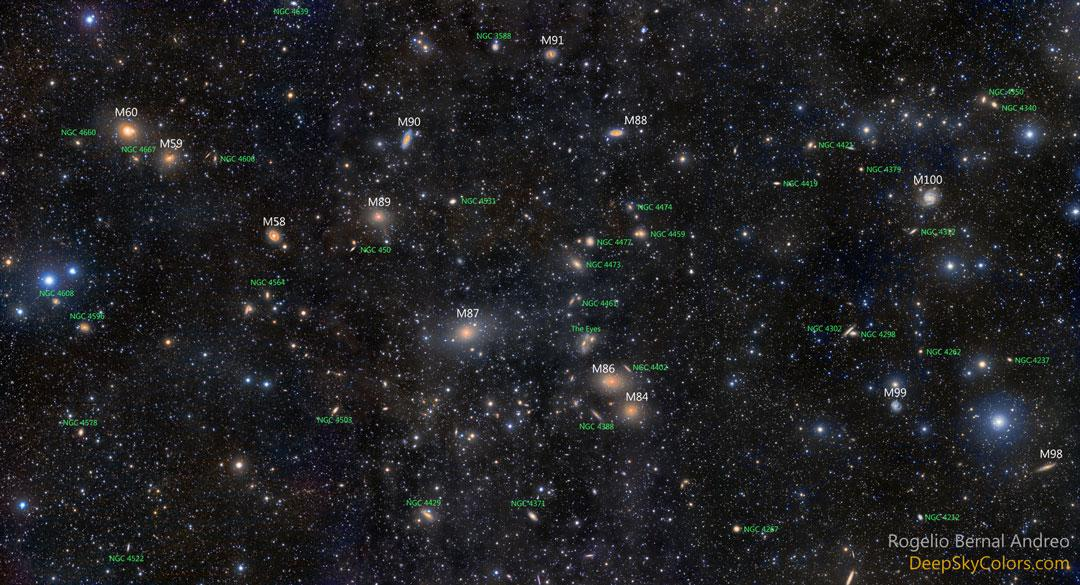

An image of the Virgo super cluster from [Astronomy picture of the day](https://apod.nasa.gov/apod/ap150804.html), this is one of the largest galaxy clusters.

## Loading the Data

The galaxy data is contained in a CSV file, we used the [matlab import data tool](https://uk.mathworks.com/help/matlab/ref/importtool-app.html) to generate a script to load the data. The script has lines to omit invalid data.

%% Initialize variables.
%filename = 'all.csv'; % uncomment this to load data for galaxies near globular clusters
filename = 'all-galaxclusters.csv'; %uncomment this to load data for the list of galaxy clusters

galaxyload %load script generated by the matlab import tool


The data is returned in a matlab [table](https://uk.mathworks.com/help/matlab/ref/table.html?searchHighlight=table&s_tid=doc_srchtitle) data type

## Using Scatter Plots to View  the Galaxy Collection

Generate cartesian coordinates using the right acension and declination. Galactic redshift is used as a proxy for radial distance.

x=all1.redshift.*sin(all1.ra).*cos(all1.dec);
y=all1.redshift.*sin(all1.ra).*sin(all1.dec);
z=all1.redshift.*cos(all1.ra);


scatter3(x,y,z);
hold on


Plot the centre of the model as a redpoint

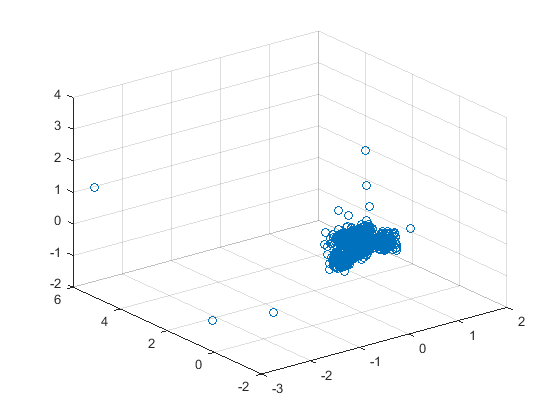

plot3(0,0,0,'r*');
hold off

Use the zoom, pan  and orientation control in the graphics window to explore different clusters. Although the algorithm has selected some galaxies with very high redshift, can you identify distinct clusters in the distribution.

## How many galaxies are observed for different redshifts?

To answer this question we use the histcounts function which returns the number of data points in each bin along with the edge positions of each bin. This is a proxy for a distribution known as a radial distribution function. The use of [radial distrbution functions](https://en.wikipedia.org/wiki/Radial_distribution_function) enables the investigation of possible correllations between the objects in our distributions.

We use the histcounts function which returns the number of objects in each bin along with the edge positions for each bin.

numbins=50;
[N,edges]=histcounts(all1.redshift,numbins);


Use the bar function to display the data as a bar chart.

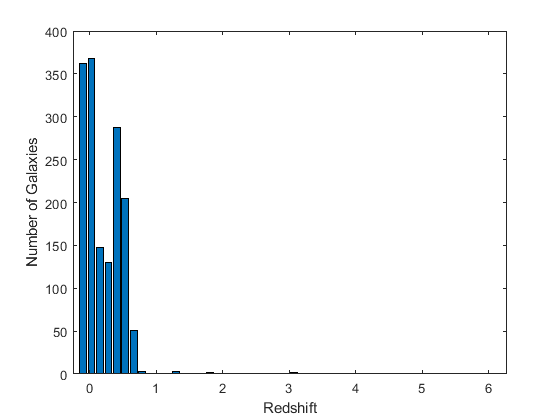

bar(edges(1:50),N);
xlabel('Redshift')
ylabel('Number of Galaxies')

We can see that most of the galaxies have a redshift less than 1.0. To see how these  are distributed in more detail we use a conditional statement to pick out all the galaxies with redshift less than 1 as shown below.

sel=all1(all1.redshift<1.0,:); %Note the additional colon


Having filtered and selected the data we require we replot the distribution

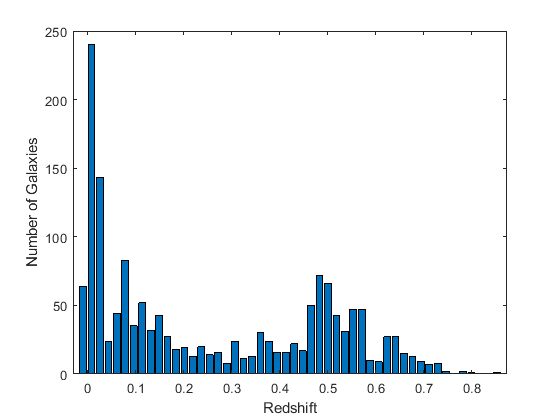

[Nsel,edges]=histcounts(sel.redshift,numbins);
bar(edges(1:50),Nsel)
xlabel('Redshift')
ylabel('Number of Galaxies')

We can see clearly from the initial scatter plot that most of the galaxies are located at redshift 0.03 and 0.1, there is a second peak around redshift 0.5. It would be interesting to how galaxies with redshift greater than 0.7 are distributed.

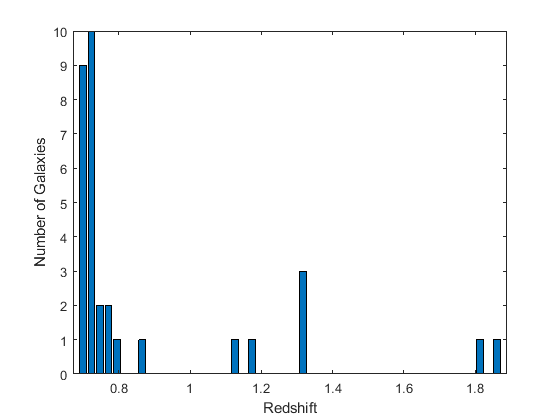


sel=all1(all1.redshift>0.7 & all1.redshift<2.0,:);
[Nsel,edges]=histcounts(sel.redshift,numbins);
bar(edges(1:50),Nsel)
xlabel('Redshift')
ylabel('Number of Galaxies')

## Interactive  Scatter Plot for the Galaxy Distribution

By making use a data filter  and by employing interactive controls Show the Distribution of galaxies for a given redshift range

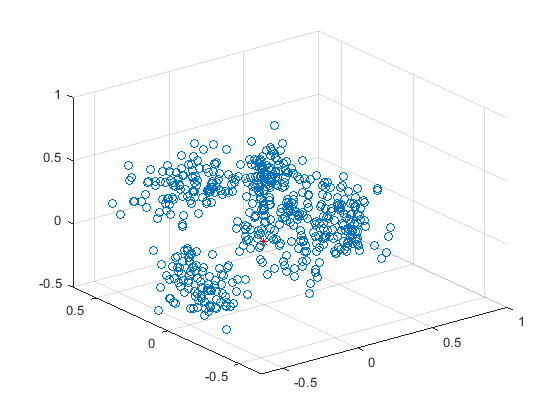

uppershift=1; %default 0.7
lowershift=0.4; %default 0.3
sel1=all1(all1.redshift>lowershift & all1.redshift<uppershift,:);

x=sel1.redshift.*sin(sel1.ra).*cos(sel1.dec);
y=sel1.redshift.*sin(sel1.ra).*sin(sel1.dec);
z=sel1.redshift.*cos(sel1.ra);

scatter3(x,y,z);
hold on

plot3(0,0,0,'r*');
hold off

## How is this Collection of Galaxies Clustered?

Lets see how galaxies are clustered together. To run the k-means cluster function we filter a section of the data set we all the vector items which we want to use to classify the set. In the first the example we use the positional information (right ascension, declination and redshift) along with the magnitude data (u,g,r,i and z). The function returns the cluster which each table entry belongs to.

%kmeans cluster
numclus=8;


A = sel1{:,{'ra','dec','u','g','r','i','z','redshift'}};
idx4 = kmeans(A,numclus);


Plot and colour the galaxies according to cluster they belong to. We use the idx4 index to colour each of the markers.

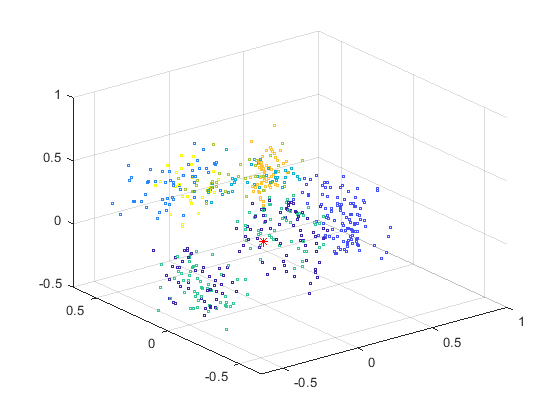

x=sel1.redshift.*sin(sel1.ra).*cos(sel1.dec);
y=sel1.redshift.*sin(sel1.ra).*sin(sel1.dec);
z=sel1.redshift.*cos(sel1.ra);

scatter3(x,y,z,3,idx4);
hold on

plot3(0,0,0,'r*');
hold off

From the above clusters it appears that some of the galaxy groups are clustered by their magnitudes.

Plot and colour the galaxies according to the magnitude cluster to which the galaxy belongs

A = sel1{:,{'u','g','r','i','z'}};
idxmag4 = kmeans(A,numclus);

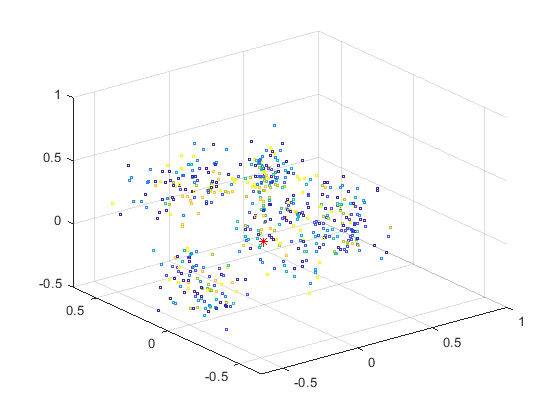

x=sel1.redshift.*sin(sel1.ra).*cos(sel1.dec);
y=sel1.redshift.*sin(sel1.ra).*sin(sel1.dec);
z=sel1.redshift.*cos(sel1.ra);

scatter3(x,y,z,3,idxmag4); %size parameter followed by colour index
hold on

plot3(0,0,0,'r*');
hold off

Clustering the galaxies using the positional data we observe well defined clusters corresponding to each of the Galaxy clusters we started with. We can conclude that none of the clusters appear to favour particular magnitude ranges. The clustering in the first test was biased by the positional data.


A = sel1{:,{'ra','dec','redshift'}};
idx4pos = kmeans(A,numclus);

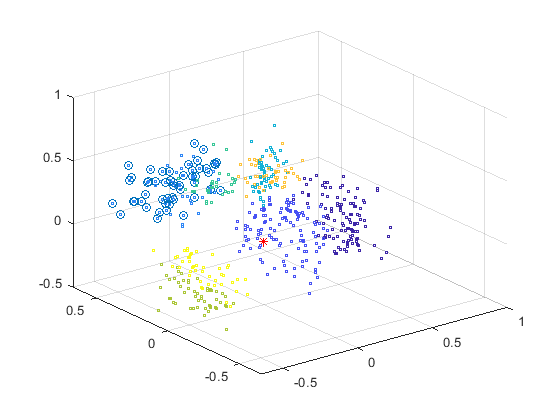



x=sel1.redshift.*sin(sel1.ra).*cos(sel1.dec);
y=sel1.redshift.*sin(sel1.ra).*sin(sel1.dec);
z=sel1.redshift.*cos(sel1.ra);

scatter3(x,y,z,3,idx4pos);
hold on

plot3(0,0,0,'r*');
hold off

Colour the galaxy using the positional clustering.

selectedclusterall=3;%select a cluster from the clustering of all selected galaxies

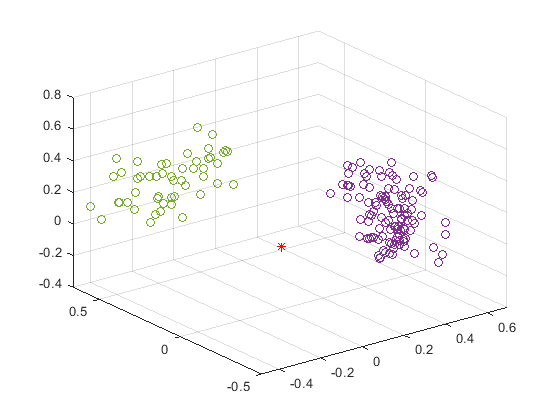

selclus=(find(idx4==selectedclusterall));
selall=sel1(selclus,:);

xall=selall.redshift.*sin(selall.ra).*cos(selall.dec);
yall=selall.redshift.*sin(selall.ra).*sin(selall.dec);
zall=selall.redshift.*cos(selall.ra);


scatter3(xall,yall,zall)
hold on
plot3(0,0,0,'r*')

## Galaxy Cluster Magnitude Analysis

What is the average magnitude of each cluster?

What is the spread of magnitudes in each cluster?

Loop over each cluster and calculate the mean magnitude for the galaxies in each cluster. Here we compute the deviation from the mean for each cluster. The computed dat ais stored in a table and the results are easily presented using bar plots.

minallu=99; %these values used to store minimum values
minallg=99;
minallr=99;
minalli=99;
minallz=99;
idallmin=ones(numclus,1);


for i=1:numclus
     selclus=(find(idx4pos==i)); %fin all the table id's for the galaxies in each cluster 
     selall=sel1(selclus,:);  %now we have the id for each galaxy select them from the full data set
     numel(selall);

    muall=mean(selall.u);
    mgall=mean(selall.g);
    mrall=mean(selall.r);
    miall=mean(selall.i);
    mzall=mean(selall.z);
    
    sz=size(selall);
    difu=0;
    difg=0;
    difr=0;
    difi=0;
    difz=0;

    for j=1:sz(1)
        dif=muall-selall.u(j);
        difu=difu+dif*dif;
        dif=mgall-selall.g(j);
        difg=difg+dif*dif;
        dif=mrall-selall.r(j);
        difr=difr+dif*dif;
        dif=miall-selall.i(j);
        difi=difi+dif*dif;
        dif=mzall-selall.z(j);
        difz=difz+dif*dif;
    end
    difallu=difu/sz(1);
    difallg=difg/sz(1);
    difallr=difr/sz(1);
    difalli=difi/sz(1);
    difallz=difz/sz(1);
    difalltot=difallu+difallg+difallr+difalli+difallz;
    
    if (difallu<minallu) %&& (i~=22) && (i~=33) %logic used to exclude selected clusters from the minimum
        minallu=difallu;
        idallmin(1)=i;
    end
    if (difallg<minallg) % && (i~=22) && (i~=33)
        minallg=difallg;
        idallmin(2)=i;
    end
    if (difallr<minallr) %&& (i~=22) && (i~=33)
        minallr=difallr;
        idallmin(3)=i;
    end
    if (difalli<minalli) % && (i~=22) && (i~=33)
        minalli=difalli;
        idallmin(3)=i;
    end    
    if (difallz<minallz)% && (i~=22) && (i~=33)
        minallz=difallz;
        idallmin(3)=i;
    end    
    
    if (difalltot<minalltot)% && (i~=22) && (i~=33)
        minalltot=difalltot;
        idallmin(4)=i;
    end
    %fprintf('All %d %d %g %g %g %g %g %g %g %g %g %g %g\n',i,sz(1),muall,difallu,mgall,difallg,mrall,difallr,miall,difalli,mzall,difallz,difalltot);

if i==1
     magtable = table(i,sz(1),muall,difallu,mgall,difallg,mrall,difallr,miall,difalli,mzall,difallz,'VariableNames',{'clusid','size','muall','difallu','mgall','difallg','mrall','difallr','miall','difalli','mzall','difallz'});
else
    magnew = table(i,sz(1),muall,difallu,mgall,difallg,mrall,difallr,miall,difalli,mzall,difallz,'VariableNames',{'clusid','size','muall','difallu','mgall','difallg','mrall','difallr','miall','difalli','mzall','difallz'}) ;
    magtable = [magtable ; magnew];
end

end

## Visual Presentation of the Magnitude Distributions

It is much easier to compare the table of mean and error values by using a visual presentation such as a stacked bar chart. The bar command takes as input and array of data. We make use of the table2array function and apply this to selected elements of the table.

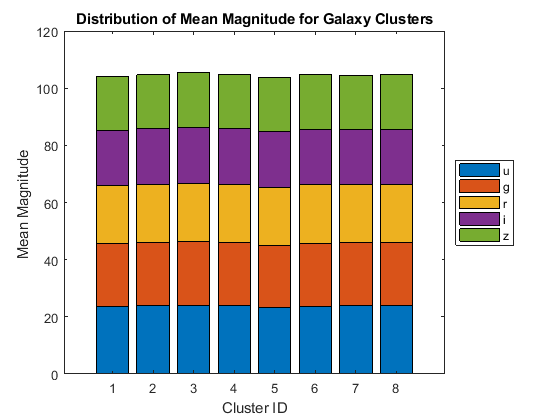

bar(table2array(magtable(:,[3 5 7 9 11 ])),'stacked')
legend('u','g','r','i','z','location','eastoutside')
title('Distribution of Mean Magnitude for Galaxy Clusters')
xlabel('Cluster ID');
ylabel('Mean Magnitude ')

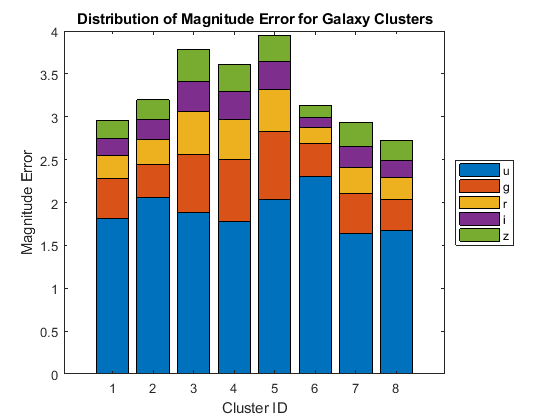

bar(table2array(magtable(:,[4 6 8 10 12 ])),'stacked')
legend('u','g','r','i','z','location','eastoutside')
title('Distribution of Magnitude Error for Galaxy Clusters')
xlabel('Cluster ID');
ylabel('Magnitude Error')

The distribution of magnitudes within each galaxy cluster is quite similar. Although there is more of a spread in the error this is much smaller than the mean value. Thus we cannot use the magnitude or a particular magnitude to distinguish the galaxy clusters.